%%%%%%%%%%%%%%%%%%%%%% Graph 3D: Operating Domian

load('xVapour Pressure.mat');
NAME_FLUID = string(cellfun(@(a) a(str2double(Fluid)+3,3),Pv(1),'UniformOutput',false))

NAME_FLUID = "WATER"

load('xMetal Propoperties Database.mat');
NAME_METAL = string(cellfun(@(a) a(str2double(Metl)+1,20),M2(1),'UniformOutput',false))

NAME_METAL = "Cu"

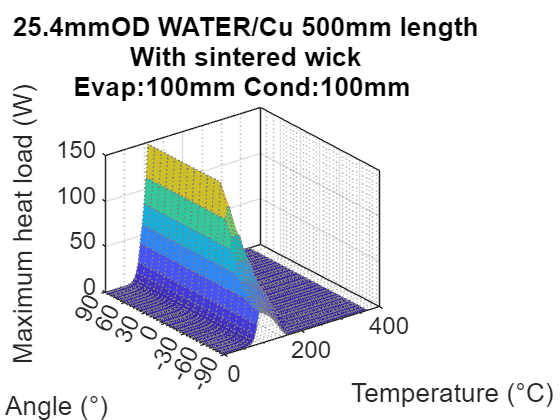


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%% 3D Graph %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Q2D = [Qcap_m90.';Qcap_m80.';Qcap_m70.';Qcap_m60.';Qcap_m50.';Qcap_m40.';Qcap_m30.';Qcap_m20.';Qcap_m10.';Qcap_0.';Qcap_10.';Qcap_20.';Qcap_30.';Qcap_40.';Qcap_50.';Qcap_60.';Qcap_70.';Qcap_80.';Qcap_90.'];

% Create figure
figure1 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

X3D = T(:,1);
Y3D = theta_range;
Z3D = Q2D;

% Create axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

surf(X3D,Y3D,real(Z3D),'Parent',axes1,'LineWidth',0.1,'LineStyle',':',...
    'EdgeColor',[0.501960813999176 0.501960813999176 0.501960813999176]);

% Create zlabel
zlabel('Maximum heat load (W)');

% Create ylabel
ylabel('Angle (°)');

% Create xlabel
xlabel('Temperature (°C)');

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe limiatations at ',{' '},string(theta),'° angle');

title({Cap_name1,Cap_name2,Cap_name3});

ylim(axes1,[-90 90]);
view(axes1,[-37.5 30]);
grid(axes1,'on');
% Set the remaining axes properties
set(axes1,'YTick',[-90 -60 -30 0 30 60 90],'YTickLabel',...
    {'-90','-60','-30','0','30','60','90'});

box(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')